Q = eye(5,5) .* 0.1;
Q(1,1) = 1;
Q(2,2) = 1;
path = [0,0,0;5,0,pi/2;5,5,0;10,5,pi/2];
[ts, q_all, tauL, tauR, xs, ys, traj_idx] = run_MPC(Q,zeros(2,2), 1,path);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
    41


Minimum found that satisfies the constraints.

Optimization completed

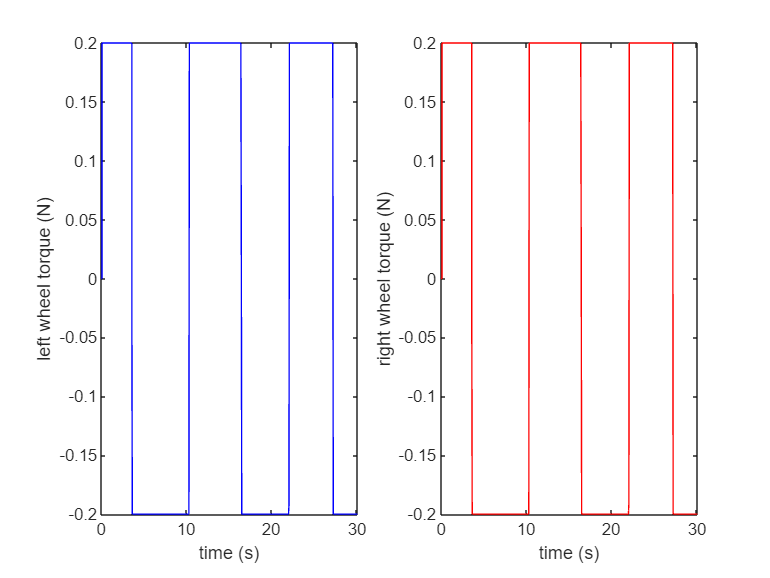


figure
hold on
subplot(1, 2, 1);
plot(ts, tauL, 'b-');
xlabel("time (s)")
ylabel("left wheel torque (N)")

subplot(1, 2, 2);
plot(ts, tauR, 'r-');
xlabel("time (s)")
ylabel("right wheel torque (N)")
hold off

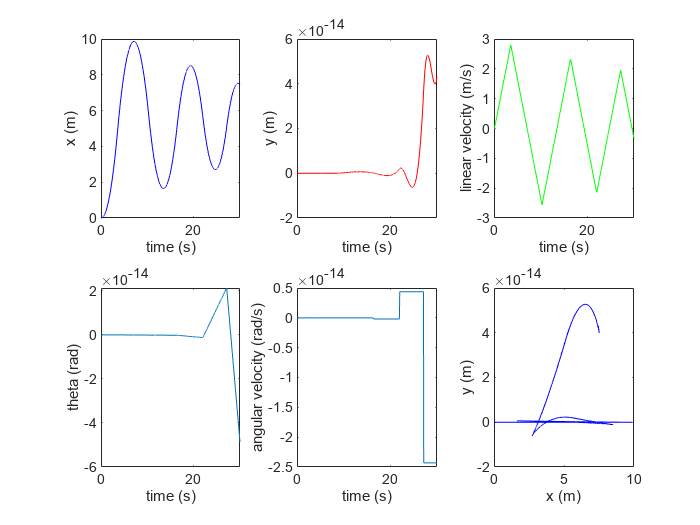


figure
hold on
subplot(2, 3, 1);
plot(ts, q_all(:,1), 'b-');
xlabel("time (s)")
ylabel("x (m)")

subplot(2, 3, 2);
plot(ts, q_all(:,2), 'r-');
xlabel("time (s)")
ylabel("y (m)")

subplot(2, 3, 3);
plot(ts, q_all(:,3), 'g-');
xlabel("time (s)")
ylabel("linear velocity (m/s)")

subplot(2, 3, 4)
plot(ts, q_all(:,4))
xlabel("time (s)")
ylabel("theta (rad)")

subplot(2, 3, 5);
plot(ts, q_all(:,5))
xlabel("time (s)")
ylabel("angular velocity (rad/s)")

subplot(2, 3, 6);
plot(q_all(:,1), q_all(:,2), 'b-');
xlabel("x (m)")
ylabel("y (m)")
hold off

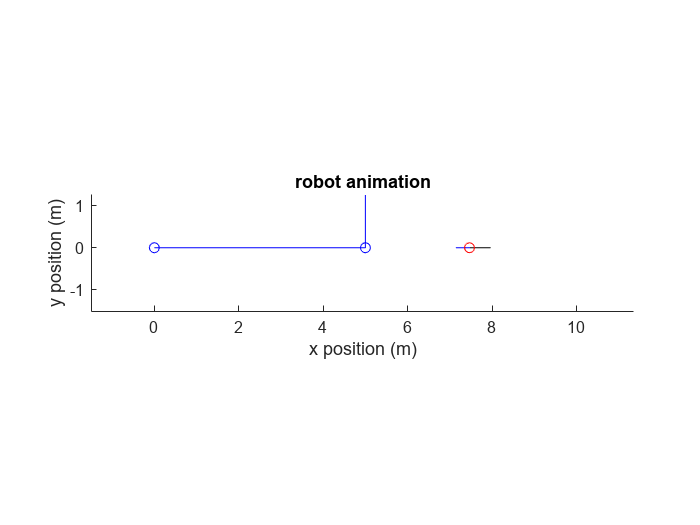

animate_mpc(ts,q_all, xs, ys, traj_idx,path);

function [t_all, q_all, torque_L, torque_R, xs, ys, traj_idx] = run_MPC(Q, R, T, path)
    % Define our Parameters
    q0 = [0;0;0;0;0]; % Initial state
    %qdes = [0;1;0;pi/2;0]; % Desired state
    path_idx = 1;
    qdes = [path(path_idx,:),0,0]';
    % Q = zeros(2,2);
    Tmax = 0.2; % Maximum torque
    
    % Simulation and MPC Control Loop   
    Tfinal = 30;
    Ts = 0.1;
    
    t_sim = 0:Ts:Tfinal;
    
    t_all = [];
    q_all = [];
    torque_L = [];
    torque_R = [];
    xs = [];
    ys = [];
    traj_idx = [];
    
    for iter = 1:numel(t_sim)
    
        % Step 1: Sample the current state
        % It's q0
    
    
        % Step 2: Formulate and Run the trajectory optimization
        % Define our Matrices/vectors for a QP
        H = Hfunc(Q,R,qdes,T);
        c = cfunc(Q,R,qdes,T);
        A = Afunc(T,Tmax);
        b = bfunc(T,Tmax);
        Aeq = Aeqfunc(q0,T,Tmax);
        beq = beqfunc(q0,T,Tmax);
        
        xstar = quadprog(H,c,A,b,Aeq,beq);
    
        % Step 3: Apply the optimal control inputs for Ts seconds 
        N = 20;
        uL = xstar(1:2:2*N-1);
        uR = xstar(2:2:2*N);
        x = xstar(2*N+1:5:7*N-4);
        y = xstar(2*N+2:5:7*N-3);
        r = 0.1; % Radius of each wheel
        L = 0.5; % Distance between wheels
        M = 5;
        d = 0;
        J = 2;
        b = 1;
        
        xs = [xs; x'];
        ys = [ys; y'];
        % have x = angular velocity spline? x = [vl1, ... vln, vr1, ... vrn, tf];
        interp_t_l = @(t) interp1(linspace(0, T, numel(uL)), uL, t);
        interp_t_r = @(t) interp1(linspace(0, T, numel(uR)), uR, t);
    
        odefun = @(t, y) odefun_torque(y, [interp_t_l(t); interp_t_r(t)], L, M, d, J, r, b);
        [tout, qout] = ode45(odefun,[0 Ts],q0);
        traj_idx = [traj_idx; ones(numel(tout),1) * iter];
        %{
        for i = 1:numel(tout)

        end
        %}
        disp(numel(tout));
        t_all = [t_all; tout+t_sim(iter)];
        q_all = [q_all; qout];
        size_tout = size(tout);
        torque_L = [torque_L; interp1(linspace(0,T,N),uL,tout)];
        torque_R = [torque_R; interp1(linspace(0,T,N),uR,tout)];
    
        for i = 1:size(qout,1)
            if norm(qdes(1:2) - qout(i,1:2)) < 0.1
                path_idx = path_idx + 1;
                qdes = [path(path_idx,:),0,0]';
            end
        end
    
        % NOW Sample the current state:
        q0 = qout(end,:).';
    
    end
end